Load data

clearvars;
clc;
[data, label] = xlsread('Health index1.csv');
data = data(:, 1:15);

Default normalise

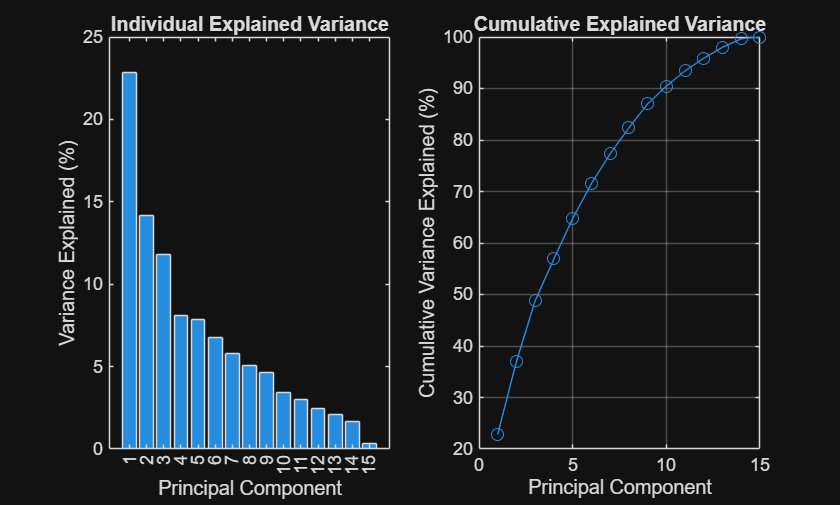

% 1 - Normalised along columns
X = normalize(data,1);
[coeff, score, latent, ~, explained] = pca(X); % X is your 470×15 data
cumulative_variance = cumsum(explained);

% Plot
figure;
subplot(1,2,1);
bar(explained);
xlabel('Principal Component');
ylabel('Variance Explained (%)');
title('Individual Explained Variance');

subplot(1,2,2);
plot(cumulative_variance, 'o-');
xlabel('Principal Component');
ylabel('Cumulative Variance Explained (%)');
title('Cumulative Explained Variance');
grid on;

Normalised by 'norm'

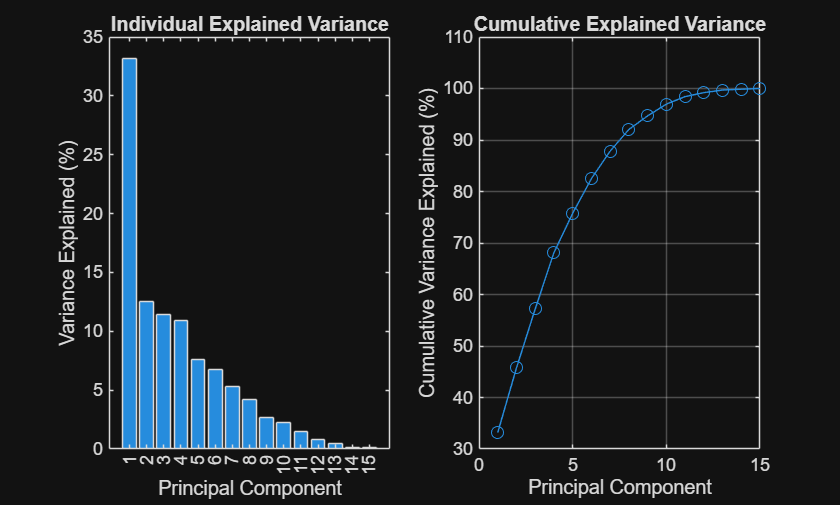

X = normalize(data,1,'norm');
[coeff, score, latent, ~, explained] = pca(X); % X is your 470×15 data
cumulative_variance = cumsum(explained);

% Plot
figure;
subplot(1,2,1);
bar(explained);
xlabel('Principal Component');
ylabel('Variance Explained (%)');
title('Individual Explained Variance');

subplot(1,2,2);
plot(cumulative_variance, 'o-');
xlabel('Principal Component');
ylabel('Cumulative Variance Explained (%)');
title('Cumulative Explained Variance');
grid on;

Normalised by 'scale' - Normalised by standard deviation by 1

X = normalize(data,1,'scale');
[coeff, score, latent, ~, explained] = pca(X); % X is your 470×15 data
cumulative_variance = cumsum(explained);

% Plot
figure;
subplot(1,2,1);
bar(explained);
xlabel('Principal Component');
ylabel('Variance Explained (%)');
title('Individual Explained Variance');

subplot(1,2,2);
plot(cumulative_variance, 'o-');
xlabel('Principal Component');
ylabel('Cumulative Variance Explained (%)');
title('Cumulative Explained Variance');
grid on;

Normalized by 'center' - mean 

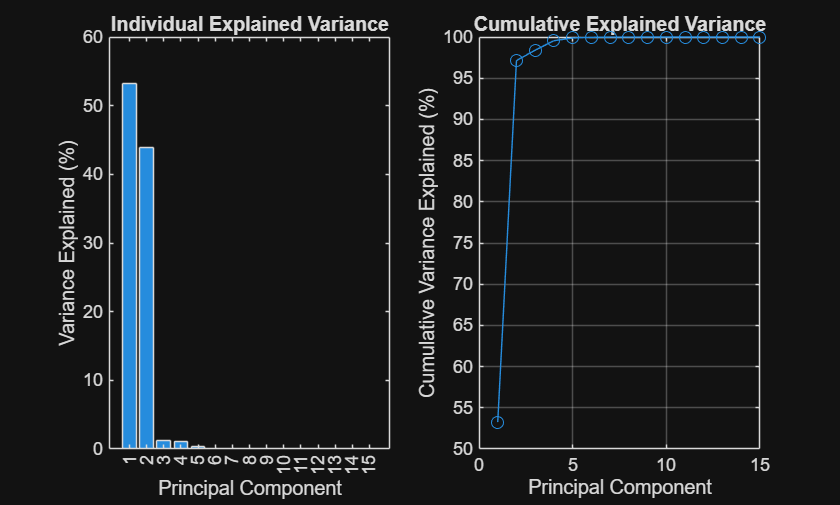

X = normalize(data,1,'center','mean');
[coeff, score, latent, ~, explained] = pca(X); % X is your 470×15 data
cumulative_variance = cumsum(explained);

% Plot
figure;
subplot(1,2,1);
bar(explained);
xlabel('Principal Component');
ylabel('Variance Explained (%)');
title('Individual Explained Variance');

subplot(1,2,2);
plot(cumulative_variance, 'o-');
xlabel('Principal Component');
ylabel('Cumulative Variance Explained (%)');
title('Cumulative Explained Variance');
grid on;

Normalized by 'center' - median

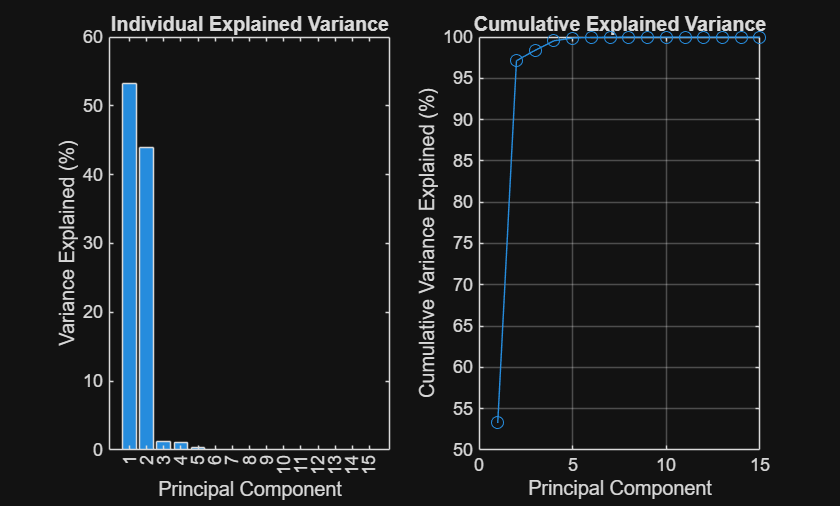

X = normalize(data,1,'center','median');
[coeff, score, latent, ~, explained] = pca(X); % X is your 470×15 data
cumulative_variance = cumsum(explained);

% Plot
figure;
subplot(1,2,1);
bar(explained);
xlabel('Principal Component');
ylabel('Variance Explained (%)');
title('Individual Explained Variance');

subplot(1,2,2);
plot(cumulative_variance, 'o-');
xlabel('Principal Component');
ylabel('Cumulative Variance Explained (%)');
title('Cumulative Explained Variance');
grid on;